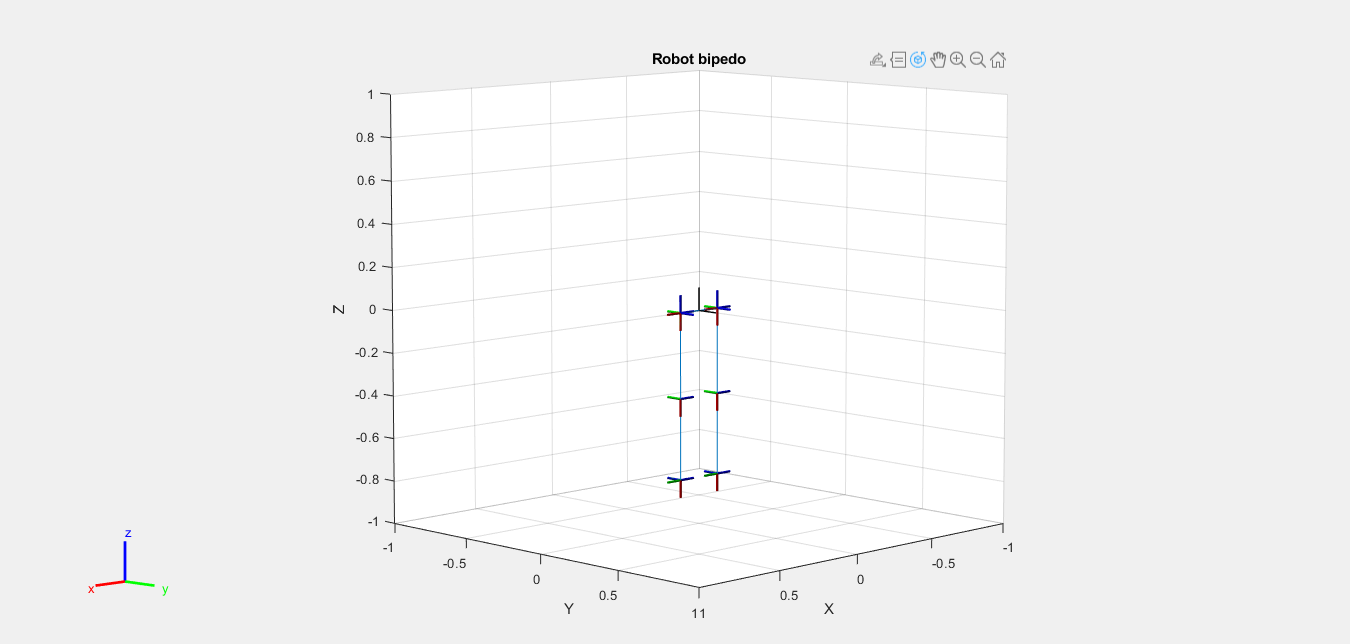

   %%%%Librería de Matlab "defaultinfos.mat"
animateOn = true; 
speedupfactor = 20;
if ~exist('footinfos','var')
    load('defaultfootinfos.mat')
end     
%%%Medidas para D-H
L1 = 0.12; %%%0
L2 = 0; %%%0.3
L3 = 0.40;
L4 = 0.38;
L5 = 0;%%%%%-0.1

%Construir robot por D-H para pierna derecha %%%%%%%   
RB = rigidBodyTree;


% Sistema Base -> cadera "hip yaw" giro en z para dirección"
                     % Hip yaw -> giro de cadera en Y para desviarse de lado a lado "hip roll"
                     % Hip roll -> giro de cadera en X para avanzar o caminar hacia atrás"hip pitch"       
                     % Hip pitch -> giro de rodilla en Y para avanzar "knee pitch"
                     % Knee pitch -> giro de tobillo en X para avanzar "ankle pitch"
                     % Ankle pitch -> giro de tobillo en Y para de lado a lado ankle roll
                     % Ankle roll -> efector final(planta del pie)
 


for i = 1:size(dhparameters,1)
    derp(i) = rigidBody("rightleg"+i); 
    derJnt(i) = rigidBodyJoint("rightjnt"+i, 'revolute'); 
    setFixedTransform(derJnt(i),dhparameters(i,:),'dh'); 
    derp(i).Joint = derJnt(i);
    if i==1
        addBody(RB,derp(i),"base");     
    else
        addBody(RB,derp(i),"rightleg"+(i-1));
    end
    
end
%%Construir pierna izquierda%%%%%%%%%%%%%%%%%%%%

        
for i = 1:size(dhparameters,1)
    izqp(i) = rigidBody("leftleg"+i); 
    izqJnt(i) = rigidBodyJoint("leftjnt"+i, 'revolute'); 
    setFixedTransform(izqJnt(i),dhparameters(i,:),'dh'); 
    izqp(i).Joint = izqJnt(i);
    if i==1
        addBody(RB,izqp(i),"base");     
    else
        addBody(RB,izqp(i),"leftleg"+(i-1));
    end
end
%%Mostrar robot Rigidbodytree
%%showdetails(robot)
hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'normalized'; 
hFig.OuterPosition = [0 0.04 1 0.96]; 
desconfig = RB.homeConfiguration; 

qright0 = zeros(1,6); 
qleft0 = zeros(1,6); 
updateJoints(RB, qright0, qleft0)

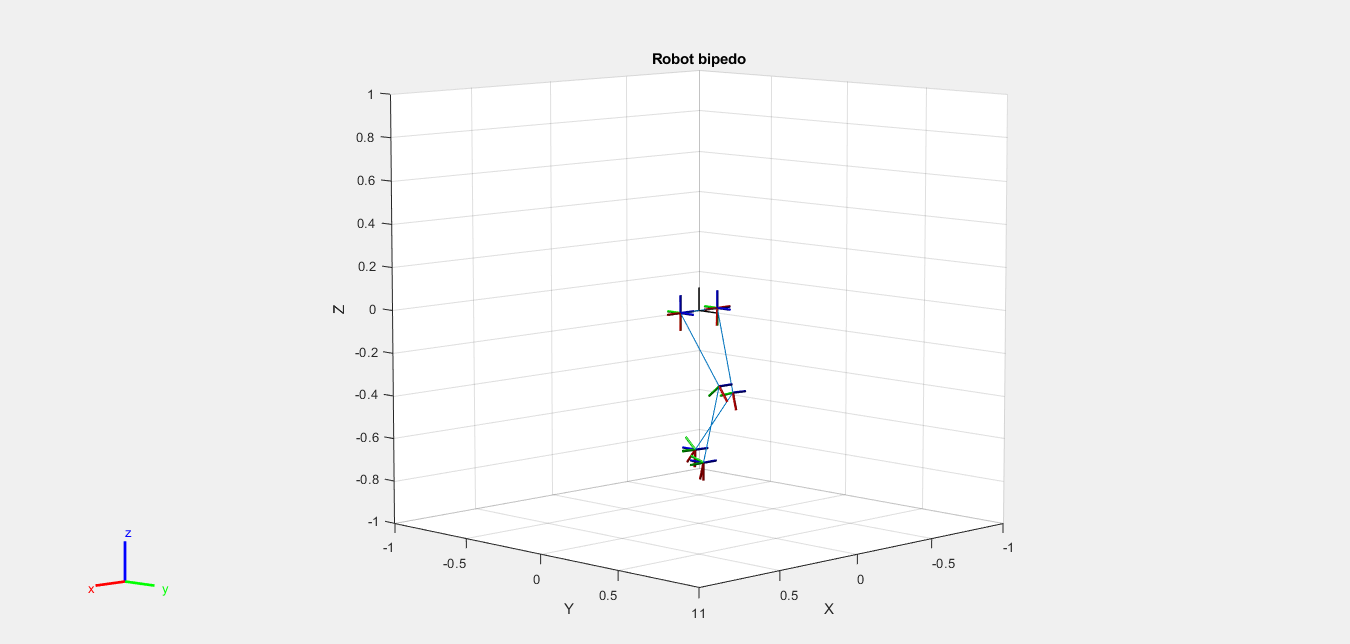

n = [0;  0; -1]; % x Posición final del efector final
s = [-1; 0; 0];  % y
a = [0;  1; 0];  % z
R = [n s a];   

for sIdx = 1:length(footinfos)
    % Extract X Y Z position states (indices 1, 3, and 5)
    stateL = footinfos{sIdx}.footleft([1 3 5],:); 
    stateR = footinfos{sIdx}.footright([1 3 5],:); 
    
    numIdx = size(stateL,2); 
    jointsLeft = zeros(6,numIdx); 
    jointsRight = zeros(6,numIdx); 
    transMatLeft = zeros(4,4,numIdx); 
    transMatRight = zeros(4,4,numIdx); 
    
    for i = 1:numIdx
        % Obtener los puntos de las articulaciones izq
        p = stateL(:,i); 
        transmat =  [R     p; 
                    [0 0 0 1]];
        isLeft = true; 
        qLeft = cininvpie(transmat, isLeft); % Llamamos a función
        jointsLeft(:,i) = qLeft; 
        transMatLeft(:,:,i) = transmat; 
        
        % Obtener los puntos de las articulaciones izq
        p = stateR(:,i); 
        transmat =  [R     p; 
                    [0 0 0 1]];
        isLeft = false; 
        qRight = cininvpie(transmat, isLeft);
        jointsRight(:,i) = qRight; 
        transMatRight(:,:,i) = transmat; 
        
     
        if animateOn%%%preguntar por condición inicial
            if rem(i,speedupfactor) == 0
                updateJoints(RB, qRight, qLeft);
            end 
        end
    end 
    footinfos{sIdx}.jointsleft = jointsLeft; %%%%%%%%Guardar todas las articulaciones
    footinfos{sIdx}.jointsright = jointsRight; 
    footinfos{sIdx}.transmatleft = transMatLeft; 
    footinfos{sIdx}.transmatright = transMatRight; 
end

timeVec = footinfos{1}.timevec; 
transMatLeft = footinfos{1}.transmatleft; 
transMatRight = footinfos{1}.transmatright; 
    
siminL.time = timeVec;
siminL.signals.values = transMatLeft;
siminL.signals.dimensions = [4,4];

siminR.time = timeVec;
siminR.signals.values = transMatRight;
siminR.signals.dimensions = [4,4];

for i = 2:length(footinfos)
    timeVec = footinfos{i}.timevec;

    transMatLeft = footinfos{i}.transmatleft; 
    transMatRight = footinfos{i}.transmatright; 

    siminL.time = [siminL.time timeVec];
    siminL.signals.values = cat(3,siminL.signals.values, transMatLeft);

    siminR.time = [siminR.time timeVec];
    siminR.signals.values = cat(3,siminR.signals.values, transMatRight);
end

function updateJoints(robot, anglesright, anglesleft)
    
    desconfig = robot.homeConfiguration;

    desconfig(1).JointPosition = pi; % angle offset 
    for idx = 1:length(anglesright)
        desconfig(idx+1).JointPosition = anglesright(idx);
    end 
    desconfig(2).JointPosition = desconfig(2).JointPosition - pi;
    desconfig(3).JointPosition = desconfig(3).JointPosition + pi/2; 
    
    desconfig(8).JointPosition = pi;
    for idx = 1:length(anglesleft)
        desconfig(idx+8).JointPosition = anglesleft(idx);
    end 
    desconfig(9).JointPosition = desconfig(9).JointPosition - pi; 
    desconfig(10).JointPosition = desconfig(10).JointPosition + pi/2; 
       
    show(robot, desconfig, 'PreservePlot', false);
    title('Robot bipedo')
    pause(0.001)
end